dat = readmatrix("sample_data_2.txt") ;
mz = dat(:,1) ;
intensity = dat(:,2) ;

tic ;
[baseline,noise] = sgolay_robust(intensity,mz,150,2,1) ;
toc

Elapsed time is 3.640625 seconds.


tic ;
[baseline_interp,noise_interp] = sgolay_robust(intensity,mz,150,2,50) ;
toc

Elapsed time is 0.077527 seconds.


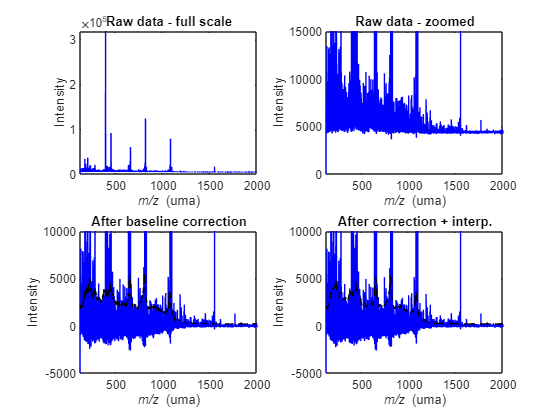

figure ;

subplot(2,2,1) ;
plot(mz,intensity,'b-') ;
xlabel("\itm/z\rm (uma)") ;
ylabel("Intensity") ;
xlim([120 2000]) ;
title("Raw data - full scale") ;

subplot(2,2,2) ;
plot(mz,intensity,'b-') ;
xlabel("\itm/z\rm (uma)") ;
ylabel("Intensity") ;
ylim([0 15000]) ; xlim([120 2000]) ;
title("Raw data - zoomed") ;

subplot(2,2,3) ;
plot(mz,intensity-baseline,'b-',mz,3*noise,'k--') ;
xlabel("\itm/z\rm (uma)") ;
ylabel("Intensity") ;
ylim([-5000 10000]) ; xlim([120 2000]) ;
title("After baseline correction") ;

subplot(2,2,4) ;
plot(mz,intensity-baseline_interp,'b-',mz,3*noise_interp,'k--') ;
xlabel("\itm/z\rm (uma)") ;
ylabel("Intensity") ;
ylim([-5000 10000]) ; xlim([120 2000]) ;
title("After correction + interp.") ;